# **TRAYECTORIA I**

**Jesús Alejandro Gómez Bautista | A01736171**

De las trayectorias solicitadas, esta es la que más problemas me genero, y aunque el resultado presentado a continuación es una aproximación bastante buena, el detalle radica en como el robot diferencial recorre esta, dicho de otra forma, se dezplaza de maner diagonal.

La apoximación para la resolución de esta trayectoria es similar a la anterior, partiendo del main trabajdo durante clase, decidí modificar la función que describe el movimeinto del robot como descriptoria de las pocisiones en y, mientras que x limita el rango en el que nuestra función trabaja [de 0 a 5 en este caso].

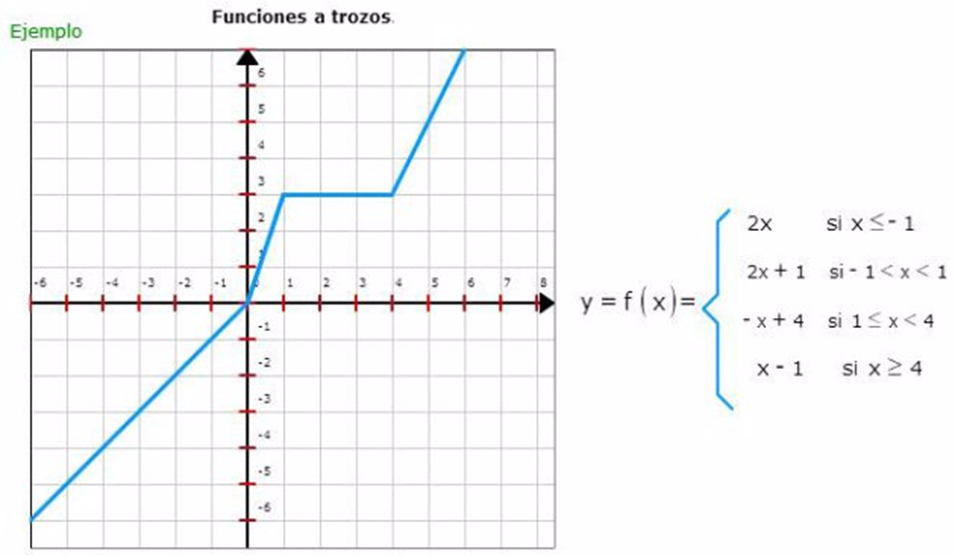

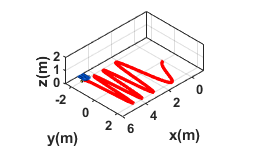

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 16;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1, N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros(1, N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 0;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

% Velocidad lineal para recorrer la trayectoria
u = 0.5*pi*5/tf;

% Parámetros de la trayectoria
x_range = linspace(0, 15, N); % Rango de x de 0 a 5
y_trajectory = 2 * sin(x_range.^2); % Trayectoria y en función de x

% Velocidad angular constante
w = 0.1 * ones(1, N); 

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N 
    
    phi(k+1) = phi(k) + w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1 = u * cos(phi(k+1)); 
    yp1 = u* sin(phi(k+1));

    x1(k+1) = x1(k) + xp1 * ts; % Integral numérica (método de Euler)
    
    % Interpolación lineal para obtener la coordenada y
    index = find(x_range >= x1(k+1), 1); % Encontrar el índice más cercano en el rango x
    if ~isempty(index)
        y1(k+1) = interp1([x_range(index-1), x_range(index)], [y_trajectory(index-1), y_trajectory(index)], x1(k+1)); % Interpolación lineal
    else
        y1(k+1) = y_trajectory(end); % Si x está fuera del rango, utilizar el último valor conocido de y
    end
    
    phi(k+1) = phi(k) + w(k) * ts; % Integral numérica (método de Euler)
    
    % Posicion del robot con respecto al punto de control
    hx(k+1) = x1(k+1); 
    hy(k+1) = y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene = figure;  % Crear figura (Escena)
set(scene, 'Color', 'white'); % Color del fondo de la escena
set(gca, 'FontWeight', 'bold') ; % Negrilla en los ejes y etiquetas
sizeScreen = get(0, 'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene, 'position', sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los ejes

view([135 35]); % Orientacion de la figura
axis([-1 6 -2.5 2.5 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

% c) Graficar Trayectorias
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

% d) Bucle de simulacion de movimiento del robot

step = 1; % pasos para simulacion

for k = 1:step:N

    delete(H1);    
    delete(H2);
    
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1, k), 'r', 'lineWidth', 2);
    
    pause(ts);

end

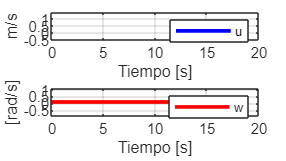


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');